## Задание 1. Спектральное дифференцирование. 

Выбираем числа $a,t_1 ,t_2$ , что $t_1 <t_2$. 

Берём функцию g, что 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\mathrm{else}
\end{array}\right.$$


% Задайте значения параметров a, t1 и t2
a = 3; dt  = 0.1;
t = -100:dt:100;
y = sin(t);
noise = a*(rand(size(t))-0.5);
y_noisy = y + noise;

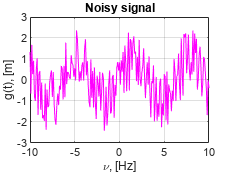

figure( randi([1 3000],1,1) )
plot(t, y_noisy, 'magenta');
grid on
title("Noisy signal")
xlim([-10;10])
xlabel('\nu, [Hz]');
ylabel('g(t), [m]');
hold off;

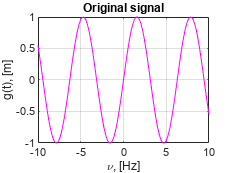


figure( randi([1 3000],1,1) )
plot(t, y, 'magenta');
grid on
title("Original signal")
xlim([-10;10])
xlabel('\nu, [Hz]');
ylabel('g(t), [m]');
hold off;

y_noisy_diff = zeros(size(t), 'double');

for i = 1:2001-1
    y_noisy_diff(i) = (y_noisy(i+1) - y_noisy(i))/dt;
end

% Находим Фурье-образ сигнала
Y_noisy = fft(y_noisy);
Y_noisy_shifted = fftshift(fft(y_noisy));
V_min = -1000; V_max = 1000;
n = 2001;
freqs = linspace(V_min, V_max, n);

% По свойству Фурье-оператора (1:end-1)
Y_noisy_diff = fftshift(2*pi*1i*freqs.*Y_noisy);

figure( randi([1 3000],1,1) )

plot(freqs, Y_noisy_diff, 'magenta');

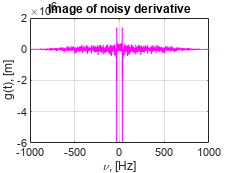


grid on
title("Image of noisy derivative")
xlabel('\nu, [Hz]');
ylabel('g(t), [m]');
hold off;


y_spectral_diff = ifft(ifftshift(Y_noisy_diff));

figure( randi([1 3000],1,1) )
plot(freqs, y_spectral_diff, 'magenta');

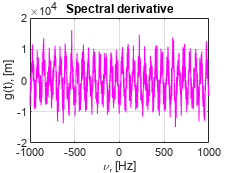

grid on
title("Spectral derivative")
xlabel('\nu, [Hz]');
ylabel('g(t), [m]');
hold off;


figure( randi([1 3000],1,1) )
plot(freqs, real(Y_noisy_shifted));
hold on
plot(freqs, imag(Y_noisy_shifted));
legend('real','imag')
xlim([-100; 100]);
title("Image of signal, ")
grid on;
xlabel('\nu, [Hz]');
ylabel('U(\nu), [Amplitude]');
hold off;
%%%%%%%%
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
Name = "image_of_numeric_diff_signal"

Name = "image_of_numeric_diff_signal"

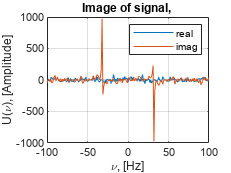

fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

%%%%%%%%

figure( randi([1 3000],1,1) )
plot(t, cos(t));
title("True derivative of sin(t) = cos(t)")
grid on;
ylim([-3/2;3/2])
xlabel('t, [sec]');
xlim([0; 100])
ylabel('A, [Amplitude]');
hold off;
%%%%%%%%
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
Name = "true_diff"

Name = "true_diff"

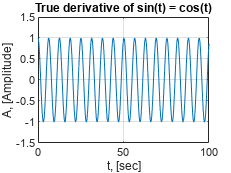

fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

%%%%%%%%
figure( randi([1 3000],1,1) )
plot(t(1:end-1), diff(y_noisy));
title("Numerical derivative of sin(t)")
grid on;
xlim([0; 20])
xlabel('t, [sec]');
ylabel('A, [Amplitude]');
hold off;
%%%%%%%%
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
Name = "numerical_diff"

Name = "numerical_diff"

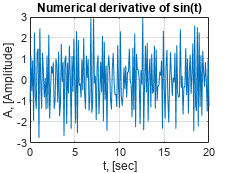

fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

%%%%%%%%
figure( randi([1 3000],1,1) )
plot(freqs, y_spectral_diff, 'magenta');

grid on
title("Spectral derivative")
xlim([0; 100])
xlabel('t, [sec]');
ylabel('A, [Amplitude]');
hold off;
%%%%%%%%
path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';
Name = "spectral_diff"

Name = "spectral_diff"

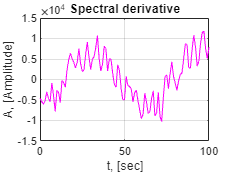

fullpath = fullfile(path, Name);
saveas(gcf, fullpath, 'png');

%%%%%%%%

Сравните график истинной производной **cos(t)** с графиками **численной** и **спектральной** производной. Выводы: как будто бы истинная производная - просто незашумлённая, в отличии от других, а у спектральной производной ещё же было домножение на частоты, поэтому уплывает

##  Все функции, используемые в скрипте